Companion software for "Volker Ziemann, *Physics and Finance, Springer, 2021*" ([https://link.springer.com/book/10.1007/978-3-030-63643-2](https://link.springer.com/book/10.1007/978-3-030-63643-2))

# Markowitz portfolio optimization (Section 3.2 and 3.3)

Volker Ziemann, 211108, CC-BY-SA-4.0

This simulation illustrates Markowitz's theory of optimizing a portfolio of stocks by minimizing the variance of the random fluctuations of the portfolio. We assume that a finite amount of money is invested with ratios $w_i$ and $\sum_i w_i=1$ into the different stocks. This constraint is taken into account by a Lagrange multiplier $\lambda_1$. Likewise, the desired return $\rho=\sum_i w_i\langle r_i\rangle$is treated as an additional constraint with the help of a second Lagrange multiplier $\lambda_2$. In Section 3.2 a portfolio with random stocks only is analyzed, while Section 3.3 treats a portfolio that also contains a risk-free asset. 

In order to test the method, we first prepare arrays with the daily returns $r_i$ of three stocks with $i=1,2,3$ for a period of `N=200` trading days. The average returns are chosen to be 0.01, 0.02, and 0.03 with a random component of the same respective magnitude added. Note also that $r_2$ is correlated with $r_1$ and that $r_3$ with the other two stocks. With rng() we chose a seed for the random number generator in order to make the simulation random, yet reproducible.

clear all; close('all')
rng(1234)   % seed random number generator
N=200;      % number of trading days
r1=0.01*ones(N,1)+0.01*randn(N,1);      
r2=0.02*ones(N,1)+0.02*randn(N,1)-0.3*r1;
r3=0.03*ones(N,1)+0.03*randn(N,1)+0.3*r1-0.5*r2;

## Portfolio with risky assets only (Section 3.2)

For Equation 3.11 we need a column vector` ee=` $\vec e$ with three ones as entries, the averaged daily returns `ra=` $\langle r_i \rangle$ and the returns with teir average subtracted` rp=` $r_i - \langle r_i\rangle$. From the latter we calculate the covariance matrix $C$ and its inverse.

ee=ones(3,1);  
ra=[mean(r1); mean(r2) ; mean(r3)];   % average return
rp=[r1-mean(r1),r2-mean(r2),r3-mean(r3)]; % for the covariance matrix
C=rp'*rp/N  % covariance matrix

C =     0.0001   -0.0000    0.0000
   -0.0000    0.0005   -0.0002
    0.0000   -0.0002    0.0012


CC=inv(C);  % and its inverse

Now we have all the ingredients to construct the matrix, here we call it A, that appears in Equation 3.16, and its inverse that appears in Equation 3.17.

A=[ra'*CC*ra , ee'*CC*ra ;     % matrix from eq. 3.16
    ra'*CC*ee , ee'*CC*ee]

A = 	1.0e+04 *

    0.0003    0.0211
    0.0211    1.5975


AA=inv(A);                     % matrix from eq. 3.17

In the following loop we iterate over many different values of the desired return $\rho$, calculate the corresponding Lagrange multipliers from Equation 3.17 and the weights $w_i$ from Equation 3.18, and store the value of $\rho$ and the overall volatility of the portfolio $\sigma^2=\vec w^TC\vec w$ where $\vec w$ is a column vector with the three weight $w_i$ as entries adn $\sigma^2$ is defined just below Equation 3.18.

K=0;
for rho=0:0.0002:0.04;  %...loop over the desired returns
    lambda=AA*[rho;1];                    % eq. 3.17
    w=lambda(1)*CC*ra+lambda(2)*CC*ee;    % eq. 3.18
    K=K+1;
    rrho(K)=rho;
    sig(K)=sqrt(w'*C*w);    % definition of sigma
end

Finally we plot the portfolio return $\rho$ versus the volatility $\sigma$  as a black line and annottate the axes.

plot(sig,rrho,'k','LineWidth',2)
xlabel('Volatility \sigma')
ylabel('Portfolio return \rho')

Into the same figure we then plot the poiunt with the smallest volatility as a red asterisk.

hold on
rhomin=-AA(1,2)/AA(1,1);         % eq.3.20
sigmin=sqrt(det(AA)/AA(1,1))     % eq.3.21

sigmin = 0.0079

plot(sigmin,rhomin,'*','LineWidth',6)
text(sigmin+0.001,rhomin,'\leftarrow Minimum risk','FontSize',12)

And then we place the volatilities and the average daily returns of the original stocks on the same plot.

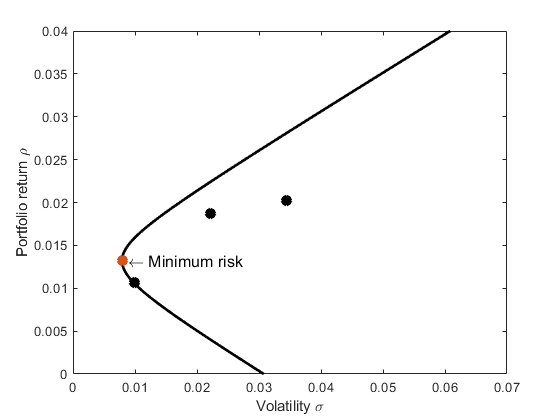

plot(sqrt(C(1,1)),ra(1),'k*',sqrt(C(2,2)),ra(2),'k*',sqrt(C(3,3)),ra(3),'k*','LineWidth',6)

We observe that the volatility of the minimum portfolio is actually slightly smaller than the smallest value if the individual volatilities--hedging and cancelling of correlated volatilities at work!

## Portfolio with a risk-free asset (Section 3.3)

In the previous section, we inverted the covariance matrix $C$, but this is not possible if we have a risk-free asset in our portfolio, because one of the columns (and rows) of $C$ contains zeros. So we have to considre this case separately here. The theory is outlined in Section 3.3. Here we assume that the risk-free return $r_f=0.08$ and then calculate $\Delta r=\langle r\rangle  -r_f\vec e$ (see top of page 22 in the book) and loop over the desired return $\rho$. Inside the loop we use Equation 3.28 to calculate the weights $\vec w$ for the different stocks and the resulting volatility.

r0=0.008;    % rate of return of the zero risk asset
deltar=ra-r0*ee;
K=0;
for rho=r0:0.0001:5*r0
    ww=(rho-r0)/(deltar'*CC*deltar)*CC*deltar;  % eq.5.22
    K=K+1;
    rrho2(K)=rho;
    sig2(K)=sqrt(ww'*C*ww);
end

Now we plot the return versus the volatility in the same plot as before, which is shown as the dashed red line, which is called the *Capital market line*, whose slope is referred to as the *Sharpe ratio*. See the discussion at the end of Section 3.3. We also place a red asterisk at the point at which the black line--the effcient frontier--and the red line meet; a portfolio with this mix of rsik-free and risky assets is called the tangent- or market portfolio. Please consult Sections 3.4 and 3.5 for further discussions.

plot(sig2,rrho2,'r--','LineWidth',2)
rhot=r0+(deltar'*CC*deltar)/(ee'*CC*deltar)

rhot = 0.0156

sigmat=sqrt((deltar'*CC*deltar)/(ee'*CC*deltar)^2)

sigmat = 0.0095

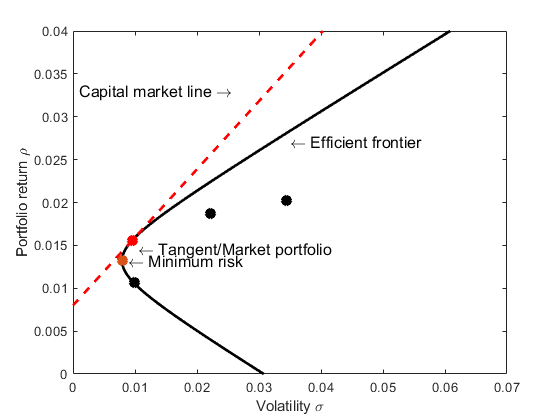

plot(sigmat,rhot,'r*','LineWidth',6)
text(sigmat+0.001,rhot-0.001,'\leftarrow Tangent/Market portfolio','FontSize',12)
text(0.035,0.027,'\leftarrow Efficient frontier','FontSize',12);
text(0.001,0.033,'Capital market line \rightarrow','FontSize',12)